# Exam 16 June 2016

## Exercise 1

clear; close all
L = 20

L = 20

q0 = [0 0 0]

q0 =      0     0     0


r = SerialLink([0 L 0 pi/2;
                0 0 L 0;
                0 0 L 0], 'name', 'three link')

 
r = 
 
three link:: 3 axis, RRR, stdDH, slowRNE                         
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         20|          0|     1.5708|          0|
|  2|         q2|          0|         20|          0|          0|
|  3|         q3|          0|         20|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


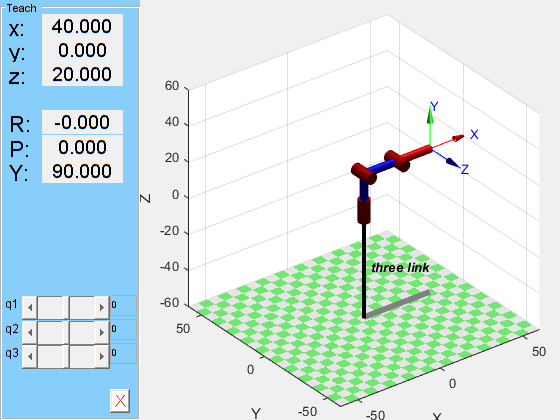

%r.plot([0 0 0])
r.teach(q0)

clear; close all
q = sym('q',[1, 6])

$$q = \left(\begin{array}{cccccc} q_{1} & q_{2} & q_{3} & q_{4} & q_{5} & q_{6} \end{array}\right)$$

syms q1 q2 q3 q4 q5 q6
dh = [pi/2 0 89.2 q1;
        0 425 0 q2;
        0 392 0 q3;
        pi/2 0 109.3 q4;
        -pi/2 0 94.75 q5;
         0 0 82.5 q6]

$$dh = \left(\begin{array}{cccc} \frac{\pi }{2} & 0 & \frac{446}{5} & q_{1}\\ 0 & 425 & 0 & q_{2}\\ 0 & 392 & 0 & q_{3}\\ \frac{\pi }{2} & 0 & \frac{1093}{10} & q_{4}\\ -\frac{\pi }{2} & 0 & \frac{379}{4} & q_{5}\\ 0 & 0 & \frac{165}{2} & q_{6} \end{array}\right)$$

T = getTranslationMatrix(dh,'alpha');

% dh2 = [ 0 89.2 0 pi/2;
%        0 0 425 0;
%        0 0 392 0;
%        0 109.3 0 -pi/2;
%        0 94.75 0 pi/2;
%        0 82.5 0 0]
%UR5  = SerialLink(dh2)
close all;
UR5  = SerialLink(getDHforTB(dh,'alpha'))

n = 6

 
UR5 = 
 
noname:: 6 axis, RRRRRR, stdDH, slowRNE                          
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|       89.2|          0|     1.5708|          0|
|  2|         q2|          0|        425|          0|          0|
|  3|         q3|          0|        392|          0|          0|
|  4|         q4|      109.3|          0|     1.5708|          0|
|  5|         q5|      94.75|          0|    -1.5708|          0|
|  6|         q6|       82.5|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


q0 = [0,pi/2,0,-pi/2,0,0]

q0 =          0    1.5708         0   -1.5708         0         0


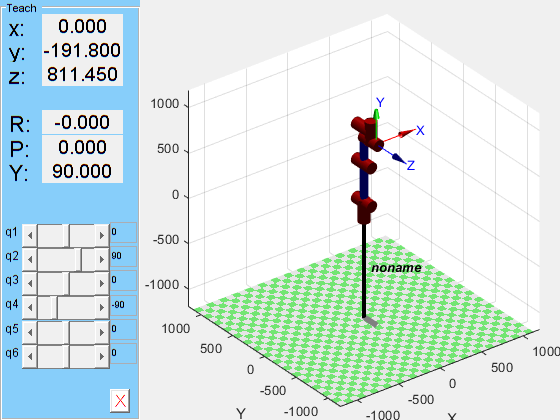

UR5.teach(q0)

## Exercise 2

%Three link planar robot
L = sym('l',[1 2]);
syms q1 q2 q3;
q = sym('q',[1,2]);
dh2 = [L(1) 0 0 q(1);
      L(2) 0 0 q(2);];
T = getTranslationMatrix(dh2);
lengths = [10 10];
T = subs(T,L,lengths)

$$T = \left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right) & 0 & 10\,\cos\left(q_{1}+q_{2}\right)+10\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & 0 & 10\,\sin\left(q_{1}+q_{2}\right)+10\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


pg = [15,15]

pg =     15    15


close all
dh2 = subs(dh2,L,lengths)

$$dh2 = \left(\begin{array}{cccc} 10 & 0 & 0 & q_{1}\\ 10 & 0 & 0 & q_{2} \end{array}\right)$$

getDHforTB(dh2)

n = 2

ans =      0     0    10     0
     0     0    10     0


robot = SerialLink(getDHforTB(dh2))

n = 2

 
robot = 
 
noname:: 2 axis, RR, stdDH, slowRNE                              
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|         10|          0|          0|
|  2|         q2|          0|         10|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


qi = [0 0] %q Initial

qi =      0     0


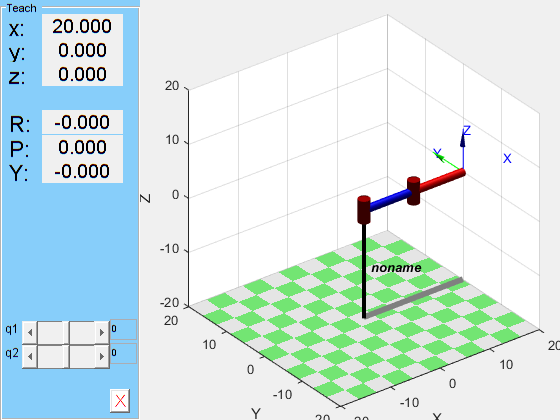

%ThreeLink.plot(qi)
robot.teach(qi)

dh2 = subs(dh2,L,lengths);
%J = getJacobian(dh2,'RRR')
%J = J(~all(J == 0,2),:)
P = T(1:2,4)

$$P = \left(\begin{array}{c} 10\,\cos\left(q_{1}+q_{2}\right)+10\,\cos\left(q_{1}\right)\\ 10\,\sin\left(q_{1}+q_{2}\right)+10\,\sin\left(q_{1}\right) \end{array}\right)$$

J=jacobian(P)

$$J = \left(\begin{array}{cc} -10\,\sin\left(q_{1}+q_{2}\right)-10\,\sin\left(q_{1}\right) & -10\,\sin\left(q_{1}+q_{2}\right)\\ 10\,\cos\left(q_{1}+q_{2}\right)+10\,\cos\left(q_{1}\right) & 10\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

pt = [0,10].'; %P_Target
q0 = [0 0].';
pc = subs(P,q.',q0);  %P_current

e = pt - pc

$$e = \left(\begin{array}{c} -20\\ 10 \end{array}\right)$$

pc = eval(subs(P,q.',q0))

pc =     20
     0


qc = q0

qc =      0
     0


qplot = [];
while(norm(e)^2 > 0.1)
    Jc = subs(J,q.',qc); %J_current
    qgrad = eval(pinv(Jc)*e);
    qc = qc+qgrad;
    pc = eval(subs(P,q.',qc));
    qplot = [qplot qc];    
    e = pt - pc;
end
pc

pc =     0.0103
    9.9854


qc

qc =    -5.7615
   14.6625


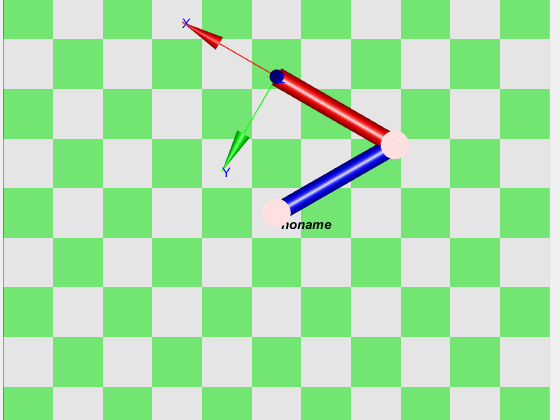

close all
robot.plot(qplot.','view','top')


% 
% while(norm(e)^2 < 10e-3)
%     e = pt - pc
%     
% end

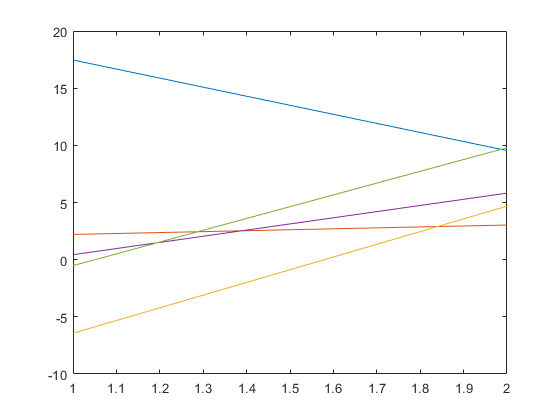

%plot(qplot)